Frank Tumminello

ECES-435 HW1

01/17/2022

clear

## **Part 1**

Create Matlab TIFF object to read tiff data from

t = Tiff("./Assignment_1_Files/pout.tif", 'r');

Read the tiff data using read function. Returns Matrix of values (Since grayscale, vals are from 0-255) Use imshow function to convert the matrix data to an image displayed out

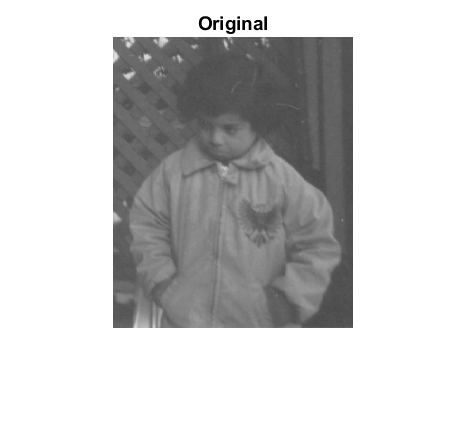

imData = read(t);
imshow(imData)
title("Original")

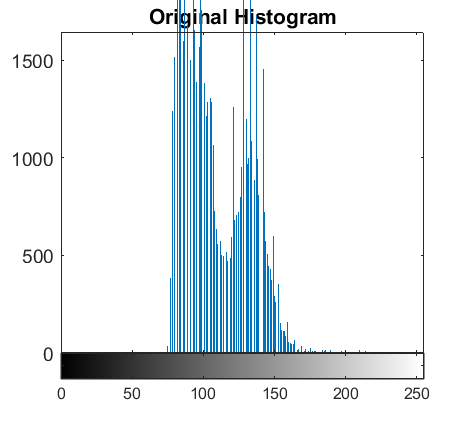

imhist(imData)
title("Original Histogram")

Use custom gammaCorrection function to change gamma of image using the matrix data and gamma value as input

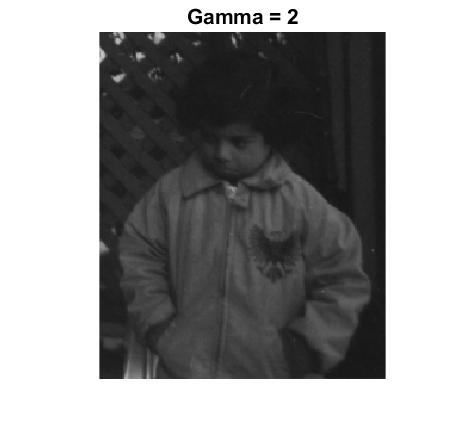

d = gammaCorrection(imData, 2);
imshow(d)
title("Gamma = 2")

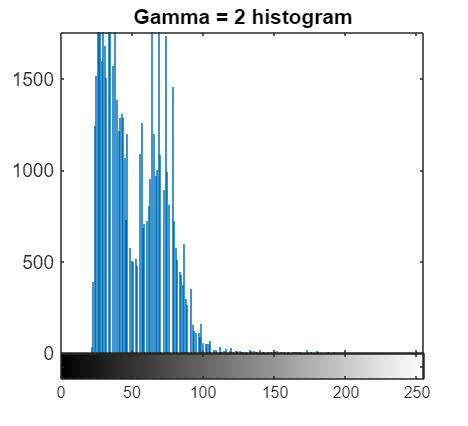

imhist(d)
title("Gamma = 2 histogram")

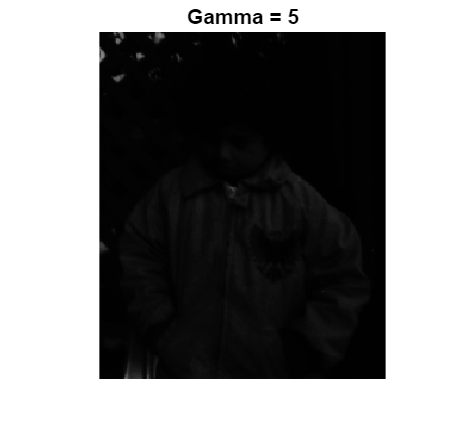


d = gammaCorrection(imData, 5);
imshow(d)
title("Gamma = 5")

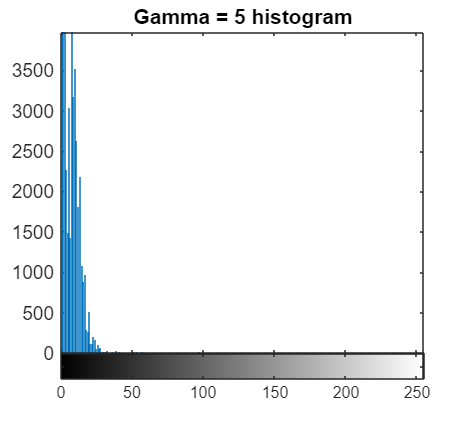

imhist(d)
title("Gamma = 5 histogram")

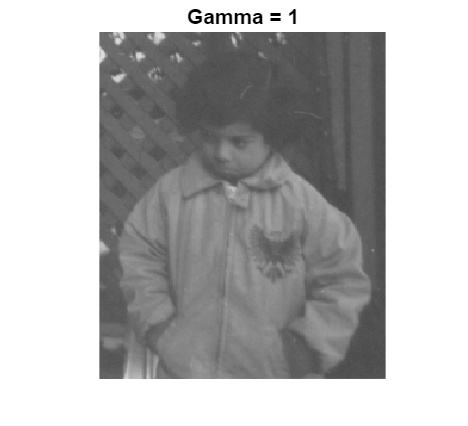


d = gammaCorrection(imData, 1);
imshow(d)
title("Gamma = 1")

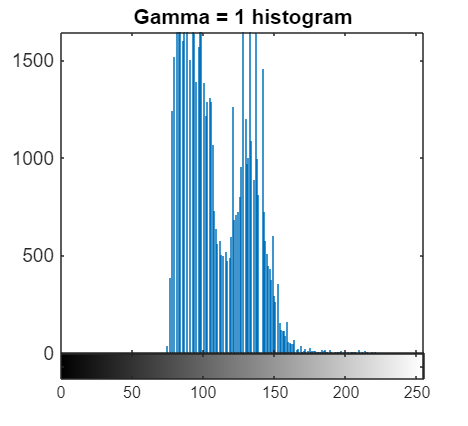

imhist(d)
title("Gamma = 1 histogram")

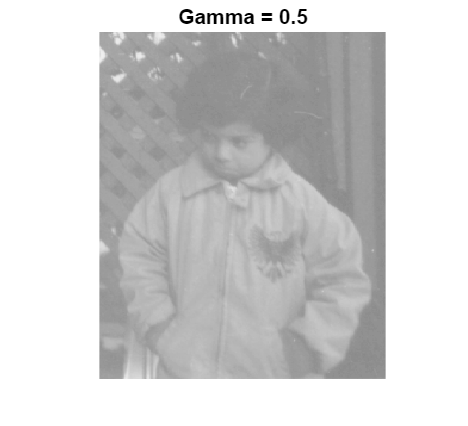


d = gammaCorrection(imData, 0.5);
imshow(d)
title("Gamma = 0.5")

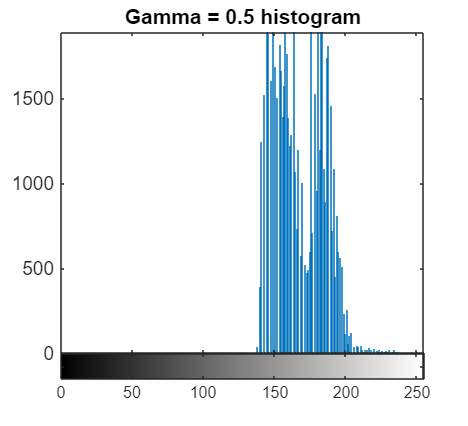

imhist(d)
title("Gamma = 0.5 histogram")

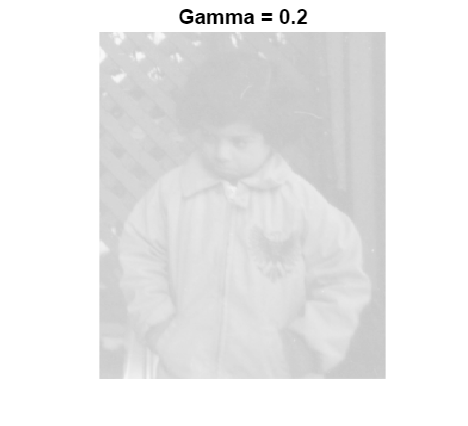


d = gammaCorrection(imData, 0.2);
imshow(d)
title("Gamma = 0.2")

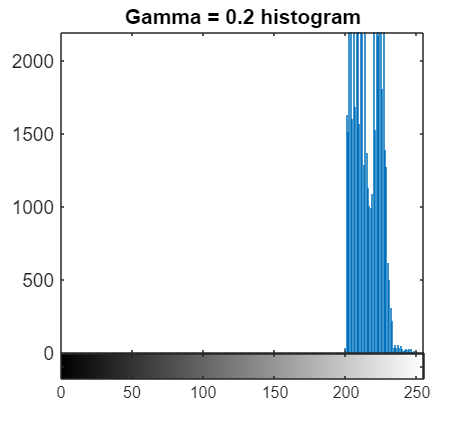

imhist(d)
title("Gamma = 0.2 histogram")

It can be seen froom the above images that gamma values above 1 create a darker image while values below 1 create lighter images. When gamma = 1 the image is unchanged (expected by looking at the equation).

This can also be expressed by the image pixel value historgrams of each image. It can be see that as gamma decrease it shifts the pixel values higher (on the 255 value scale; closer to white) while also making the pixel distributiong narrower. However, while the gamma values increase the pixel values decrease (closer to 0 value scale; closer to black) also making the distribution of pixel values narrower.

Now using the custom gamma correction function we will adjust the gamma of MoonPhobos.tif to enhance the image

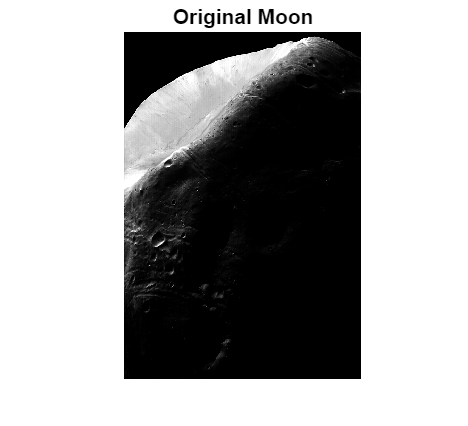

moonTiff = Tiff("./Assignment_1_Files/MoonPhobos.tif", 'r');
moonData = read(moonTiff);
imshow(moonData)
title("Original Moon");

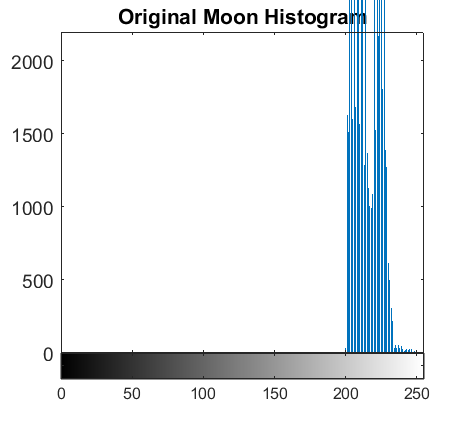

imhist(d)
title("Original Moon Histogram")

It can be seen that the image is quite dark. Therefore, we will gamma correct with a gamma below 1 to enhance the image.

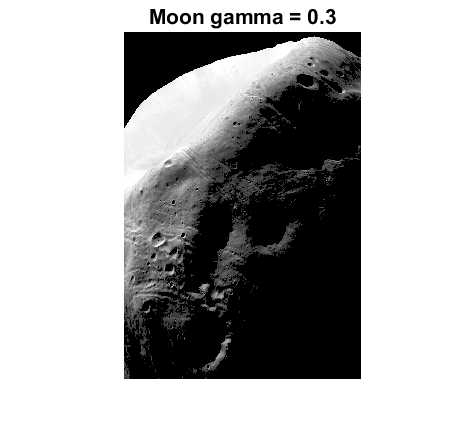

d = gammaCorrection(moonData, 0.3);
imshow(d)
title("Moon gamma = 0.3")

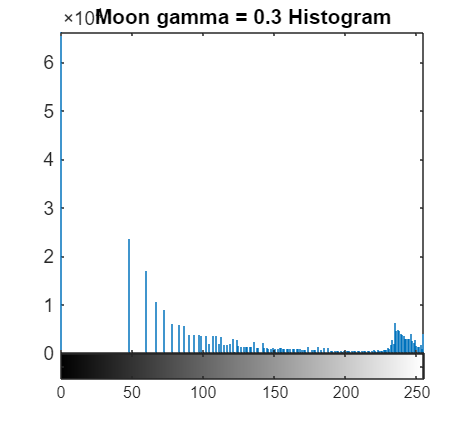

imhist(d)
title("Moon gamma = 0.3 Histogram")

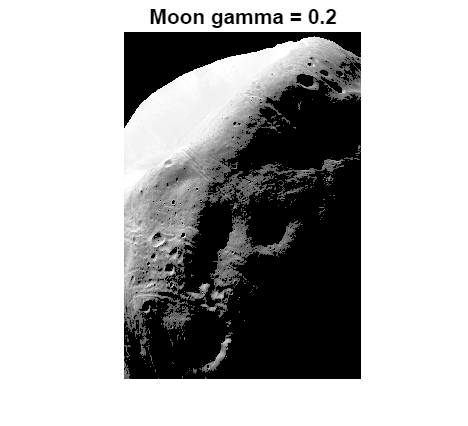


d = gammaCorrection(moonData, 0.2);
imshow(d)
title("Moon gamma = 0.2")

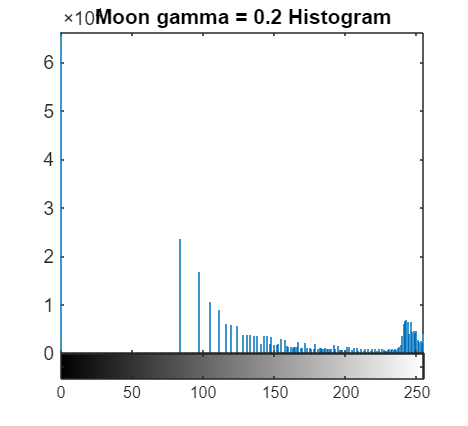

imhist(d)
title("Moon gamma = 0.2 Histogram")

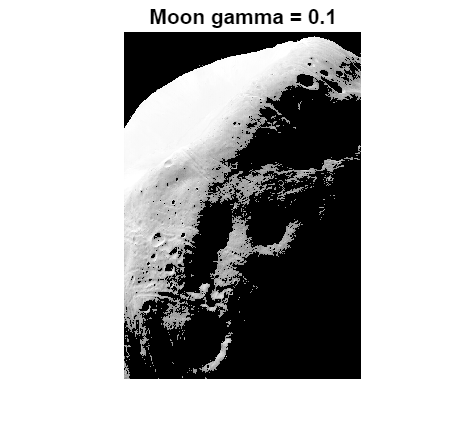


d = gammaCorrection(moonData, 0.1);
imshow(d)
title("Moon gamma = 0.1")

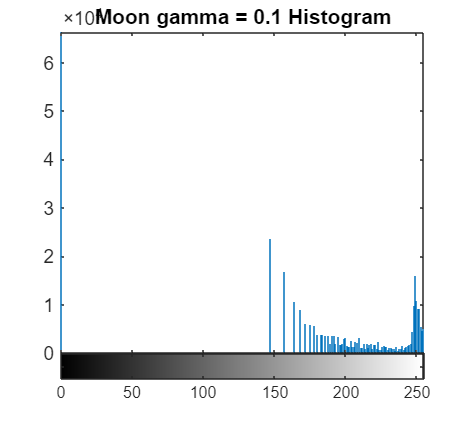

imhist(d)
title("Moon gamma = 0.1 Histogram")

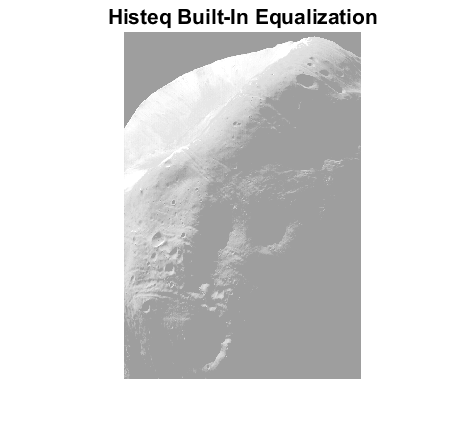


histeq(moonData)
title("Histeq Built-In Equalization")

After testing gamma values, it can be found that gamma = 0.2 allows visibility of most of the craters with minimal distortion. However, to see all craters gamma could be lowered to as low as 0.1, however, the image is quite distorted.

When comparing the results of custom gamma correction function and built-in histeq function, it is quite evident that the custom gamma correction image is better enhanced. The distribution of values resulted from the histeq function is much narrower causing the contrast in the image to look poor. Resulting in a similiar image as the original just on the opposite end of the pixel value spectrum.

## Part 2

Create custom image high boost filtering function

=====================================

1.) Find g(x,y) via convulution of original image with the laplacian filter

2.) Multiply g(x,y) with scalar value denoted by alpha

3.) Add resulting product with original image data

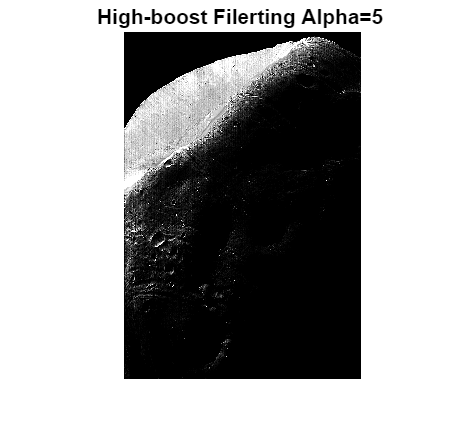

d = highBoost(moonData, 5);
imshow(d)
title("High-boost Filerting Alpha=5 ")

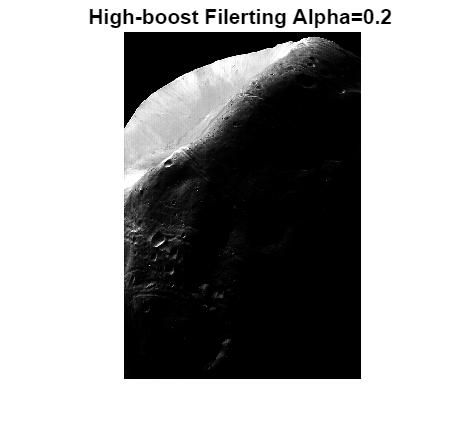


d = highBoost(moonData, 0.2);
imshow(d)
title("High-boost Filerting Alpha=0.2 ")

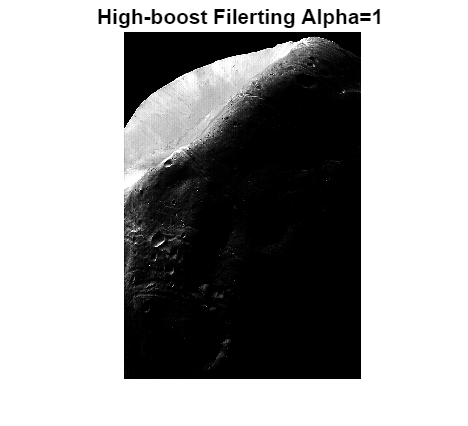


d = highBoost(moonData, 1);
imshow(d)
title("High-boost Filerting Alpha=1 ")

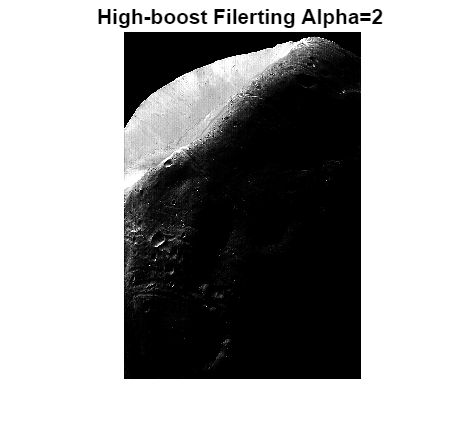


d = highBoost(moonData, 2);
imshow(d)
title("High-boost Filerting Alpha=2 ")

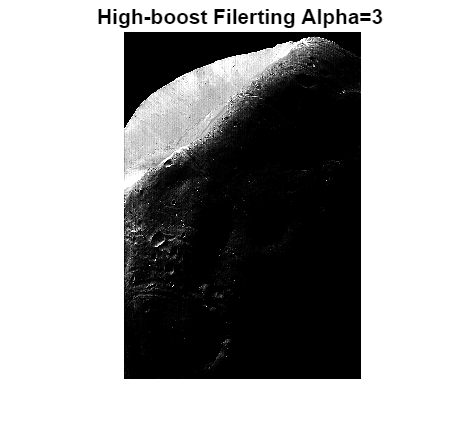


d = highBoost(moonData, 3);
imshow(d)
title("High-boost Filerting Alpha=3 ")

After running the custom high-boost filtering to enchance the moon image, I believe that an alpha of 3 works best. In this high boost filtering, we are highlighting edges (in this case craters in the moon) with higher integer pixel values (white). This enables us to more easily see the craters on the moon with minimal distortion.

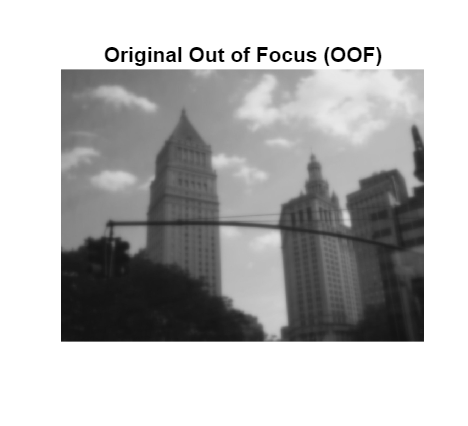

focusTif = Tiff("./Assignment_1_Files/outoffocus.tif", 'r');
focusData = read(focusTif);
imshow(focusData)
title("Original Out of Focus (OOF)")

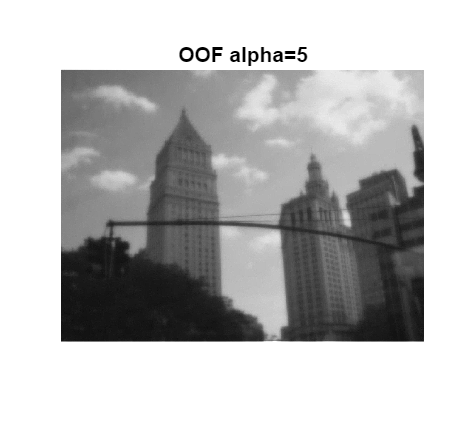


d = highBoost(focusData, 5);
imshow(d)
title("OOF alpha=5")

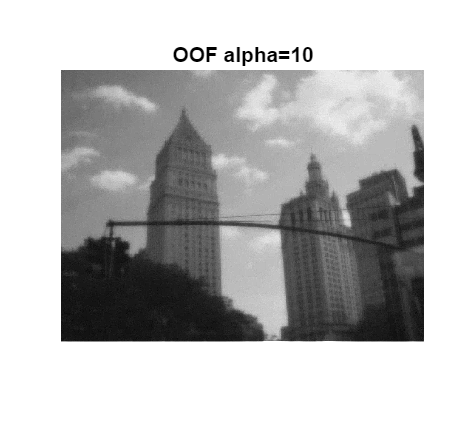


d = highBoost(focusData, 10);
imshow(d)
title("OOF alpha=10")

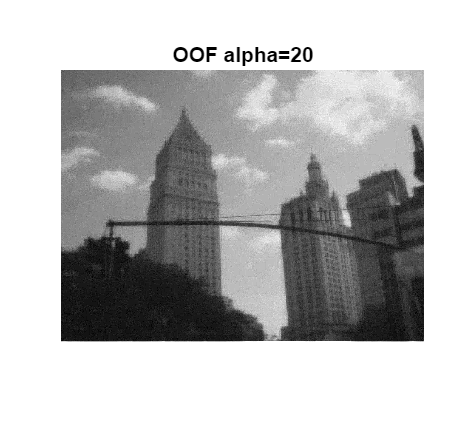


d = highBoost(focusData, 20);
imshow(d)
title("OOF alpha=20")

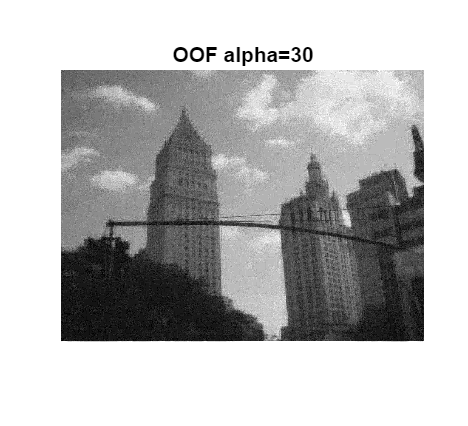


d = highBoost(focusData, 30);
imshow(d)
title("OOF alpha=30")

After running the custom boost function on the outoffocus.tif image, I belive that an alpha of 20 works best as the picture comes into relatvie focus with little distorition. It can be seen that the image is enhanced by viewing the traffic light. The traffic light was unrecoginizable in the original, while in the enhanced image it was clear what the object was. It can be seen that when alpha gets too high the image becomes very grainy and distorts the image quality. Essentially taking a blurry image and making it look lower resolution.

## Part 3